# DMD pattern Design

## Special pattern generate

%% common params setting
dmd_size = 256; % dmd size
Cr = 10         % compressive ratio

Cr = 10

dmd_type = 'center_circle'

dmd_type = 'center_circle'

dmd_type:

'center_circle'

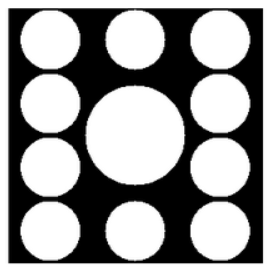

%% dmd generate
if strcmp(dmd_type, 'center_circle')
    % params
    center_circle_r = 50
    out_cricle_r = 30
    
    % generate dmd
    dmd = zeros([dmd_size dmd_size Cr]);
    
    for i = 1:3
        tmp_dmd = cyl(dmd_size, center_circle_r);
        tmp_dmd = cyl(tmp_dmd, out_cricle_r, [dmd_size/8, dmd_size/6*(2*i-1)]);
        dmd(:,:,i) = tmp_dmd;
        
        tmp_dmd = cyl(dmd_size, center_circle_r);
        tmp_dmd = cyl(tmp_dmd, out_cricle_r, [dmd_size/8*7, dmd_size/6*(2*i-1)]);
        dmd(:,:,11-i) = tmp_dmd;
    end
    
    for i = 1:2
        tmp_dmd = cyl(dmd_size, center_circle_r);
        tmp_dmd = cyl( tmp_dmd, out_cricle_r, [dmd_size/8*(2*i+1), dmd_size/6]);
        dmd(:,:,i+3) = tmp_dmd;
        tmp_dmd = cyl(dmd_size, center_circle_r);
        tmp_dmd = cyl( tmp_dmd, out_cricle_r, [dmd_size/8*(2*i+1), dmd_size/6*5]);
        dmd(:,:,i+5) = tmp_dmd;
    end    
    
    
    
end

center_circle_r = 50

out_cricle_r = 30

## save dmd

saving_path = './designed_dmd/'

saving_path = './designed_dmd/'

saving_name = [dmd_type '_dmd_' num2str(dmd_size) '_' num2str(Cr) 'f.mat'];
save([saving_path saving_name], 'dmd');

## append functions

function z = cyl(N,R,P)
% CYL generates samples of a continuous, aperiodic, unity-height cylinder 
% at the points specified in P with radius R (percent of the length) on a background 
% rectangle with size N.
% 
%   Input:
%   --------
%   - N: 2-elements int vector, background rectangle size
%	- P: 2-elements int vector,centre point of the cylinder, default=[0,0]
%	- R: float scalar, radius of the cylinder
%   Output:
%   --------
%   - z: unity-height cylinder 

% input check
if numel(N)==1
	N = [N,N];		% background size
	z = zeros(N);	% background
elseif ~isvector(N)
	z = N;			% background
	N = size(z);	% background size
end

if nargin < 3
	P = round(N./2);
end

x0 = P(1);
y0 = P(2);
L1 = N(1);
L2 = N(2);

[x,y]=meshgrid(linspace(1, L1, L1), linspace(1, L2, L2)); 
x = x';
y = y';

r = sqrt((x-x0).*(x-x0)+(y-y0).*(y-y0)); % distance map

z(r<=R) = 1;
end